## **Practical Problems 4 – Errors & Bracketed Root Finding**

1. **[Overflow Error] **Matlab returns **Inf** when an overflow error in double precision is encountered. Write a script that starts with *n* = 1, calculates *n*! and increases *n* until overflow occurs (number is too big that Matlab can’t handle it). Display the value of *n* that represents the largest factorial that Matlab can handle.

n = 0;
not(isinf(n))

ans = logical
   1


while not(isinf(factorial(n)))  
    n = n + 1;
end
n

n = 171

2. **[Rounding Error]** Approximate the sequence {*πn*} for *n* = 1 to 18 by rounding π to 1, 2, 4, and 8 decimal places. Calculate the absolute error for each sequence approximation from the sequence that uses *π *with double precision. Plot the errors for each approximate sequence on the same plot with y-axis between 0 and 5. See if you can figure out how to embed smaller plots within the main plot that zoom in on each of the sequences.

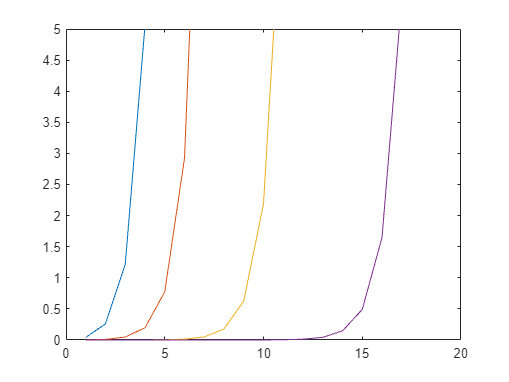

x = [];
y = 1:18;
for m = 0:3
    appPi = round(pi, 2.^(m));
    for n = 1:18
        x(end+1) = abs(pi^n - appPi^n);
    end
end
plot(y, x(1:18), y, x(19:36), y, x(37: 54), y, x(55: 72))
ylim([0,5])

3. **[Truncation Error]** The Maclaurin series for cos(*x*) is 

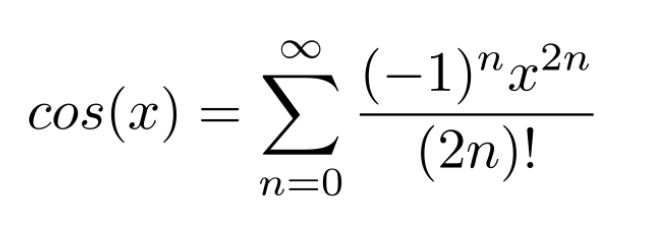

Plot the cosine function in a thick black line between –2π and 2π. On the same graph plot the Maclaurin series approximation for *n* equal to 2, 4, 8 and 16.

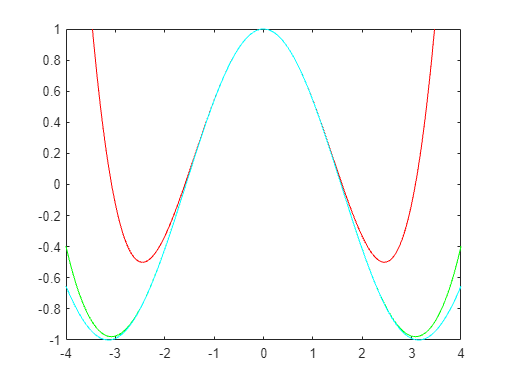

x = -2 * pi : 0.01 : 2 * pi;
nn = 2.^(1:4);
y2 = [];
index = [];
syms n x1
for o = 1:length(nn)
    F(x1) = symsum(((-1)^n * x1^(2*n))/factorial(2 * n), n, 0, nn(o));
    for p = -2 * pi : 0.01 : 2 * pi
        y2(end + 1) = F(p);
    end
    index(end + 1) = length(y2);
end

plot(x, cos(x),'Black', x, y2(1:index(1)),'red', x, y2((index(1)+1):index(2)), 'green', x, y2((index(2)+1):index(3)), 'blue' , x, y2(index(3)+1:end), 'cyan')
xlim([-4, 4])
ylim([-1, 1])

5. **[True vs. Relative Error]** The Maclaurin series for *ex* is 

Plot the true function from 0 to 5 then on the same graph plot the Maclaurin approximations for *n* equal to 1, 2, 4, 8, and 16. Calculate the true absolute and true relative errors then plot these together in a separate graph.

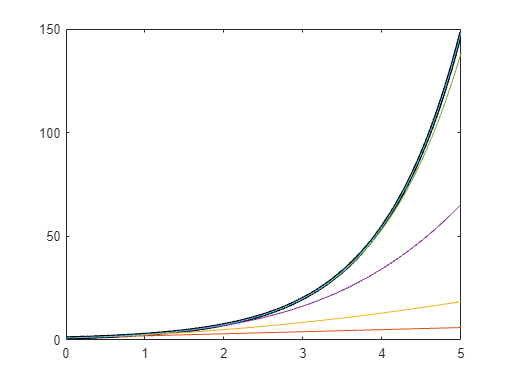

x1 = 0 : 0.01 : 5;
ansCell = cell(5, 1);
syms x  n1
for m = 0:4
    a = [];
    n = 2^m;
    F(x) = symsum((x^n1)/factorial(n1), n1, 0, n);
    for o = 0 : 0.01 : 5
        a(end + 1) = F(o);
    end
    ansCell{m + 1} = a;
end
plot(x1, exp(x1), LineWidth=2.5, Color="black");
hold on;
plot(x1, ansCell{1}, x1, ansCell{2}, x1, ansCell{3}, x1, ansCell{4}, x1, ansCell{5});
hold off;

6. **[Convergence with Absolute Error Criterion]** The series 

is convergent. Write a script that finds the value the series converges to by using a loop and the absolute approximate error with a tolerance of 0.0001 (stopping criterion).

tolLim = 0.0001
n = 0
a = 0
while n < tolLim
    